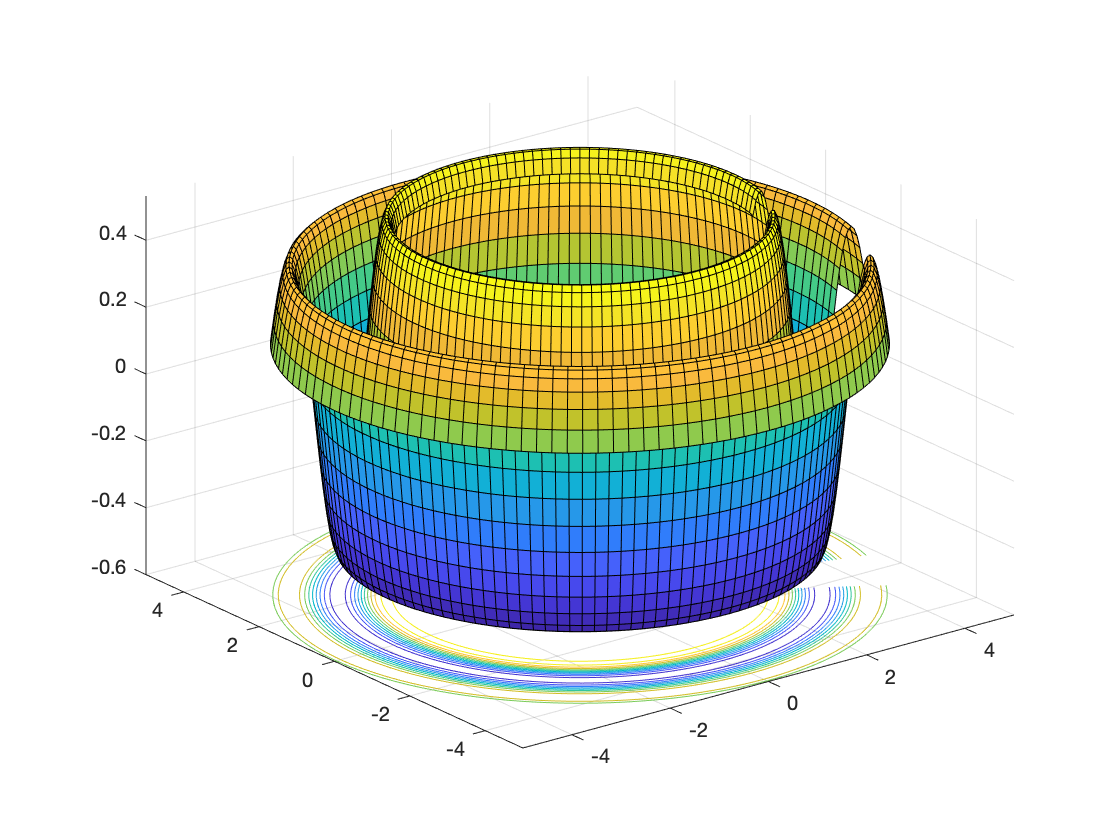

a=1;
mu=0.2;
omega=4;
phi=pi/2;
r_min=input('r_min=');
r_max=input('r_min=');
u_min=input('u_min=');
u_max=input('u_max=');
u=u_min:0.05:u_max;
r=r_min:0.05:r_max;
[U,R]=meshgrid(u,r);
X=cos(U).*R;
Y=sin(U).*R;
Z=a*exp(R.*(-mu)).*sin(R.*omega+phi);
title('Поверхность с затухающими окружными волнами');
mesh(X,Y,Z);
colorbar('horiz');
xlabel('x');
ylabel('y');
zlabel('z');